## Criticality Analysis

### Neuronal Distance Matrix

cd D:\Light-Sheet-Data-Processing-Script\matlab_visualization\
load("tile_centerofmass.mat")

CoM_array;
dist_vec = pdist(CoM_array,"euclidean");
dist_mat = squareform(dist_vec)

dist_mat =          0   52.2741   95.8574  139.0537  179.2368   86.3949   62.4500   42.4820  186.4595   74.7915  163.0048  201.0111   69.1071  145.9161  158.4497  164.8664  223.0912  189.2432  105.4783  113.5799  224.9856   99.4046  107.8178   96.5653  127.5613   35.7461   27.9566  171.3377   10.2175   14.7117   32.4941   30.5006   38.9088   26.6241  106.5968   49.2744   22.4192  155.6012  149.9076  109.8271   62.2163   44.8583   32.7434   30.5254   20.0639   34.9609   24.2473   27.0735   40.7821   30.8245
   52.2741         0  137.5365  182.2847  223.4633   34.3844   13.5543   30.0509  228.1916   30.2808  201.7623  241.6771   71.4138  182.6873  194.6482  201.9791  261.5394  226.6917   59.3959   78.4217  258.4875  151.3436  159.8439  148.4762  177.2030   46.4932   57.2971  221.3603   42.9263   57.4671   77.7028   79.7798   83.3296   72.3671  152.2428    4.1210   57.8302  199.3461  195.0171   58.3046   14.3609   21.2063   34.5751   39.7226   45.6893   47.9128   43.2962   49.6157   62.07

%delete dist_vec

### Covariance Distance Scatter

cov_mat = cov(lpf_zscore_arr');
tmp_mask = triu(true(size(cov_mat)),1);
cov_vec = cov_mat(tmp_mask);
delete tmp_mask

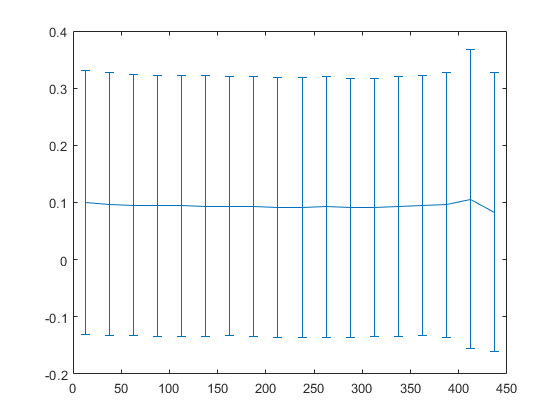

bins = linspace(0,450,19);
mean_cov_vec = zeros([1,length(bins)-1]);
std_cov_vec = zeros([1,length(bins)-1]);
for i = 1:length(bins)-1
    mean_cov_vec(i) = mean(cov_vec(dist_vec < bins(i+1) & dist_vec > bins(i)));
    std_cov_vec(i) = std(cov_vec(dist_vec < bins(i+1) & dist_vec > bins(i)));
end
errorbar((bins(1:end-1)+bins(2:end))/2,mean_cov_vec,std_cov_vec)

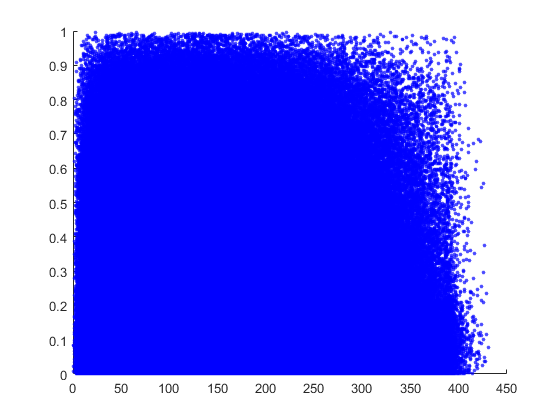

scatter(dist_vec, abs(cov_vec)',9,"blue",'filled','MarkerFaceAlpha',0.7)